[x, Fs] = audioread("4_tobias.wav");

x = x(:, 1);

%x = x(550000:end-100000);


params

N = length(x);
t = (0:N-1)/Fs;
N/Fs;

plot

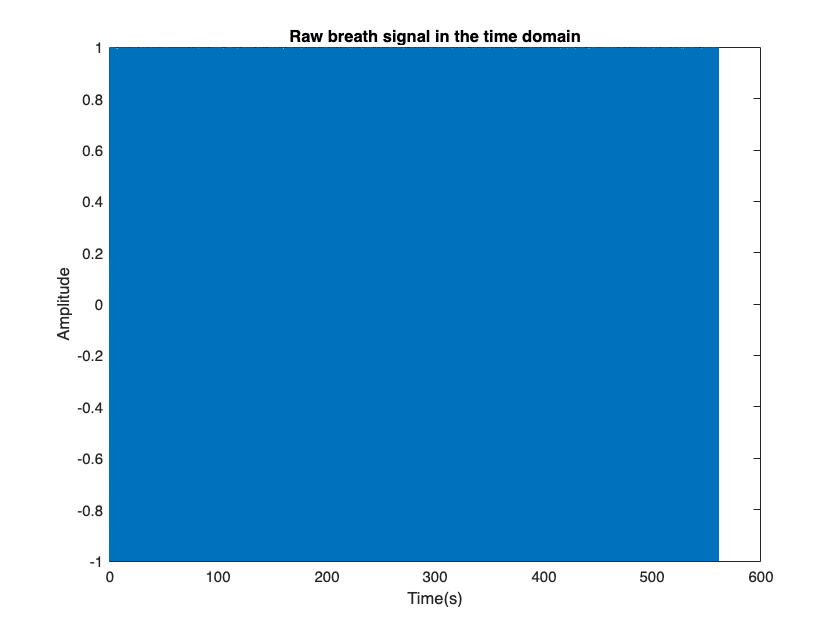

figure
plot(t,x); title('Raw breath signal in the time domain'); %x is the signal 
xlabel('Time(s)')
ylabel('Amplitude')

plot in freq domain

NFFT = 1024

NFFT = 1024

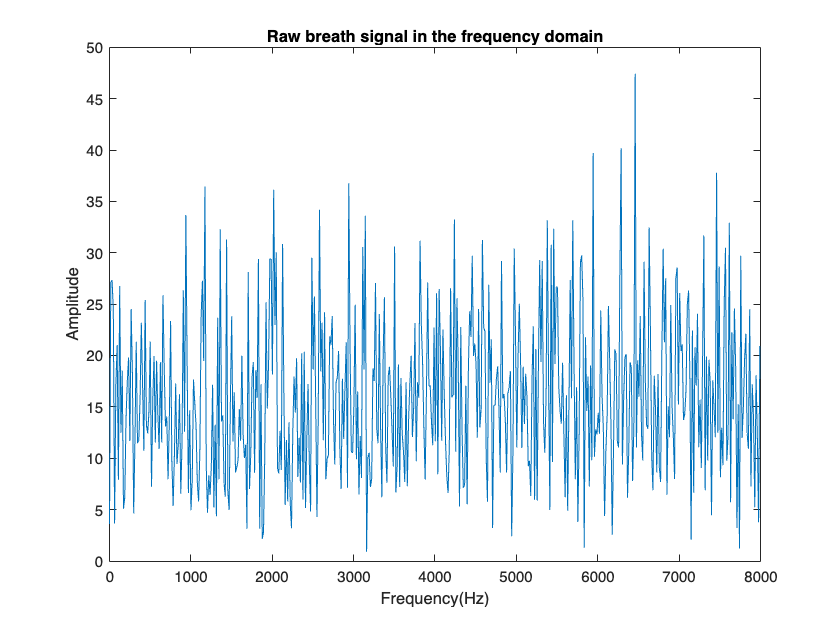

f = linspace(0,Fs,NFFT);
X = abs(fft(x,NFFT));

figure
plot(f(1:NFFT/2),X(1:NFFT/2)); title('Raw breath signal in the frequency domain'); %x is the signal 
xlabel('Frequency(Hz)')
ylabel('Amplitude')

FFT

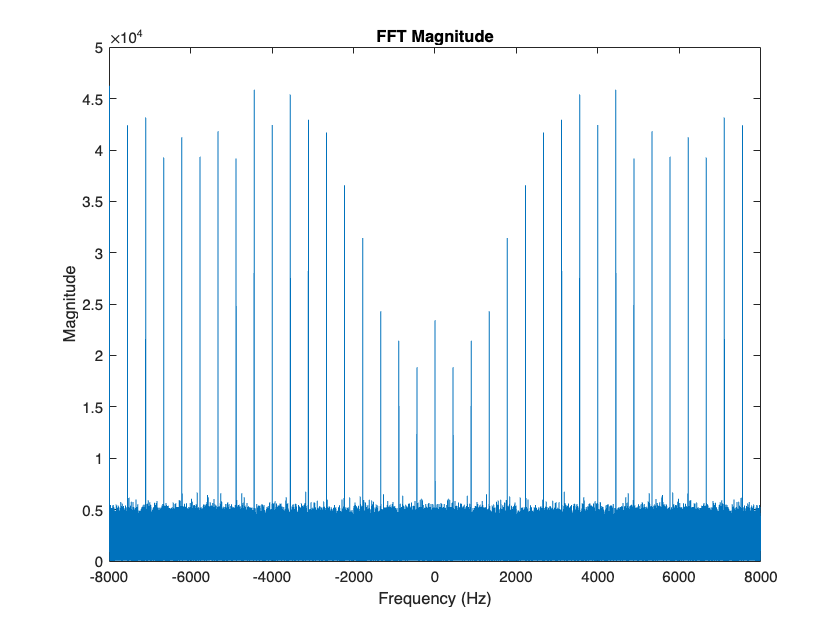

y = fft(x);
yshift = fftshift(y);
fshift = (-N/2:N/2-1)*Fs/N;

figure;
plot(fshift, abs(yshift));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('FFT Magnitude');

Noise

% rng("default");
% xnoise = x + 2.5*randn(size(t));
% 
% ynoise = fft(xnoise);
% ynoiseshift = fftshift(ynoise);
% power = abs(ynoiseshift).^2/N; 
% plot(fshift,power)
% title('Power')
% xlabel('Frequency (Hz)')
% ylabel('Power')

Filter

n = 7;
beginFreq = 330/(Fs/2);
endFreq = (3300)/(Fs/2);  
%for 1m use 500 to 4000
%for 3m use 330 to 3300
[b,a] = butter(n, [beginFreq,endFreq], "bandpass");
[H,W] = freqz(b,a,n);

xout = filter(b,a,x);
% figure;
% plot(20*log10(abs(H)))

plot filtered signal

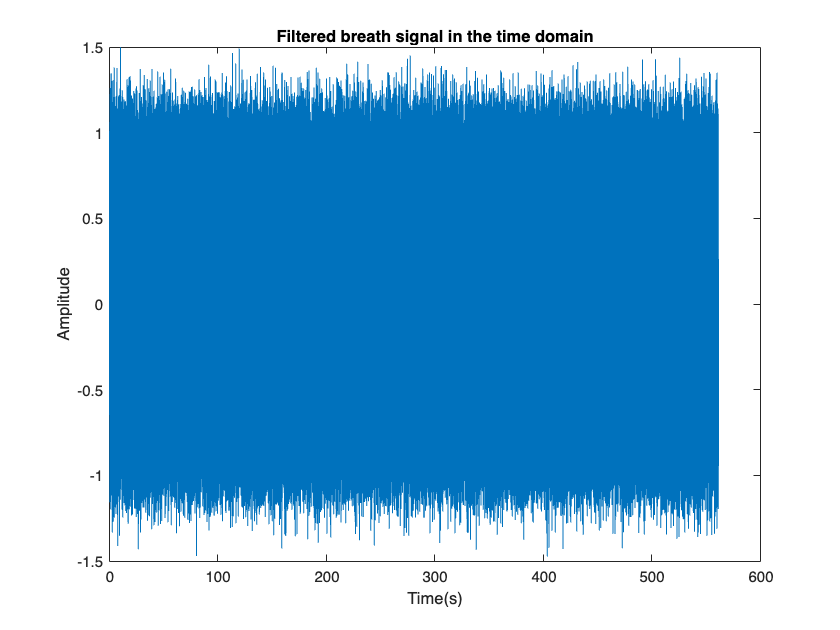

figure
plot(t,xout); title('Filtered breath signal in the time domain'); %x is the signal 
xlabel('Time(s)')
ylabel('Amplitude')


NFFT = 1024

NFFT = 1024

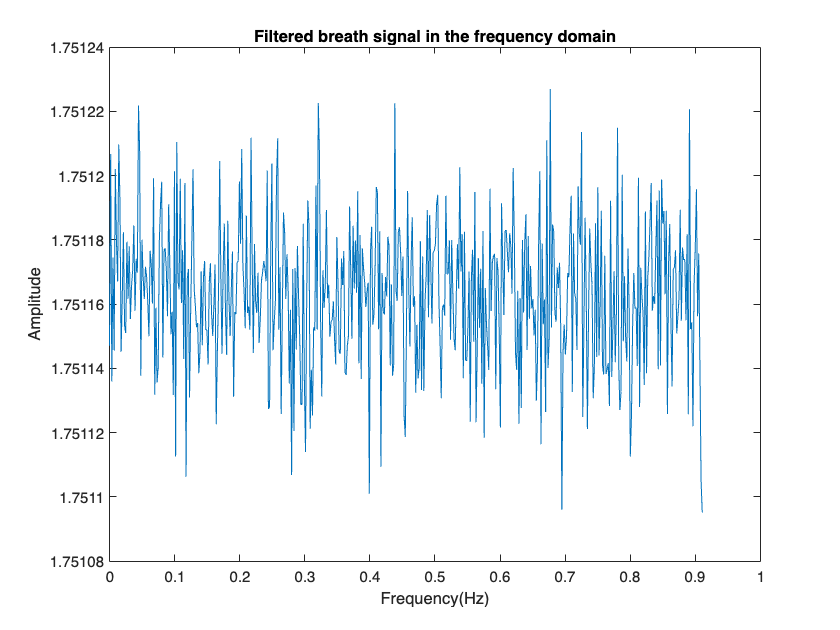

f = linspace(0,Fs,N);
Xout = abs(fft(xout,N));

figure
plot(f(1:NFFT/2),Xout(1:NFFT/2)); title('Filtered breath signal in the frequency domain'); %x is the signal 
xlabel('Frequency(Hz)')
ylabel('Amplitude')

Hanning window

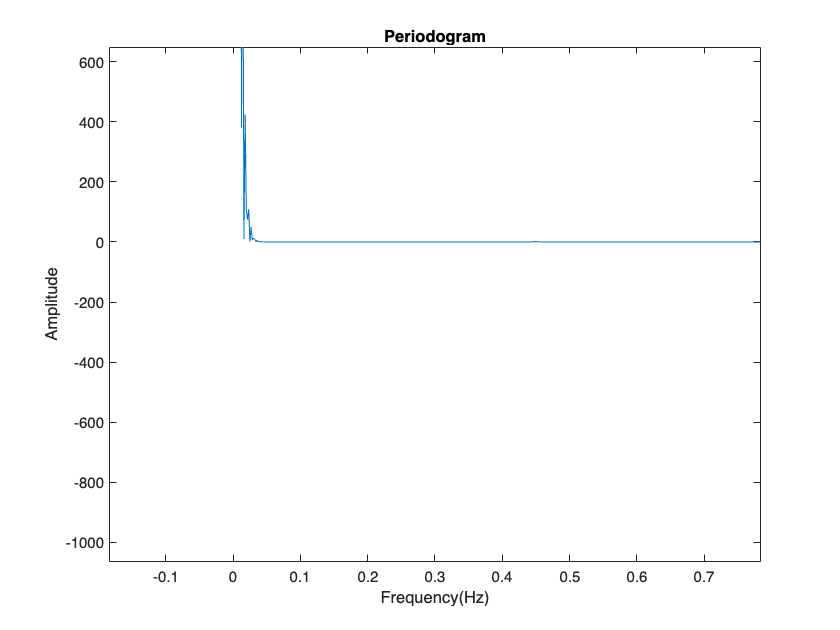

%bandpass already applied

w = hanning(N, "periodic");  %hanning window to apply over signal
[P, pw] = pwelch(Xout, w, 500, N, Fs, "power");  %returns periodogram

figure
plot(pw, P)
title('Periodogram'); %before env
xlabel('Frequency(Hz)')
ylabel('Amplitude')

hilbert transform

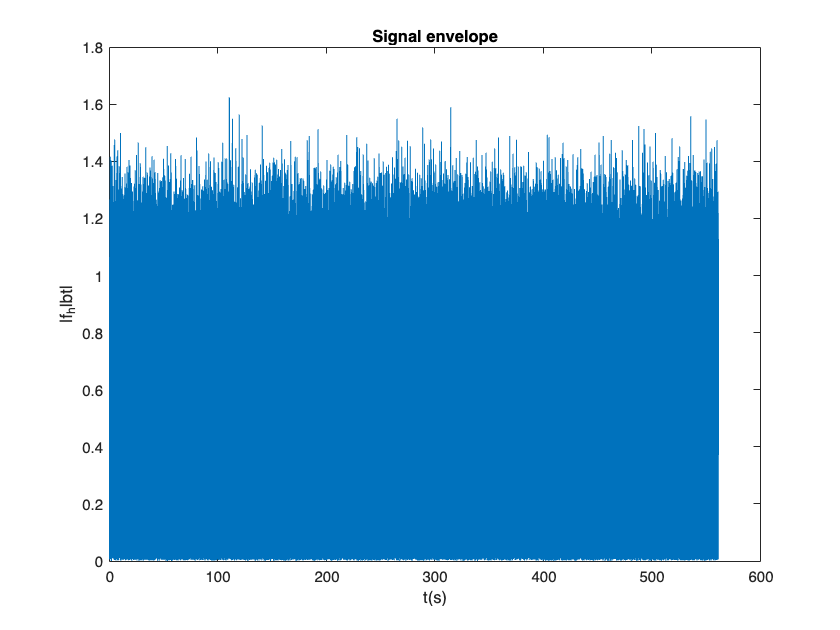

%x_bpf = bandpass(x,[500 4500],Fs);

x_env = abs(hilbert(xout));
[x_env, lower] = envelope(xout);
figure
plot(t, x_env); title('Signal envelope');
xlabel('t(s)'); ylabel('|f_hlbt|');

periodogram from envelope signal

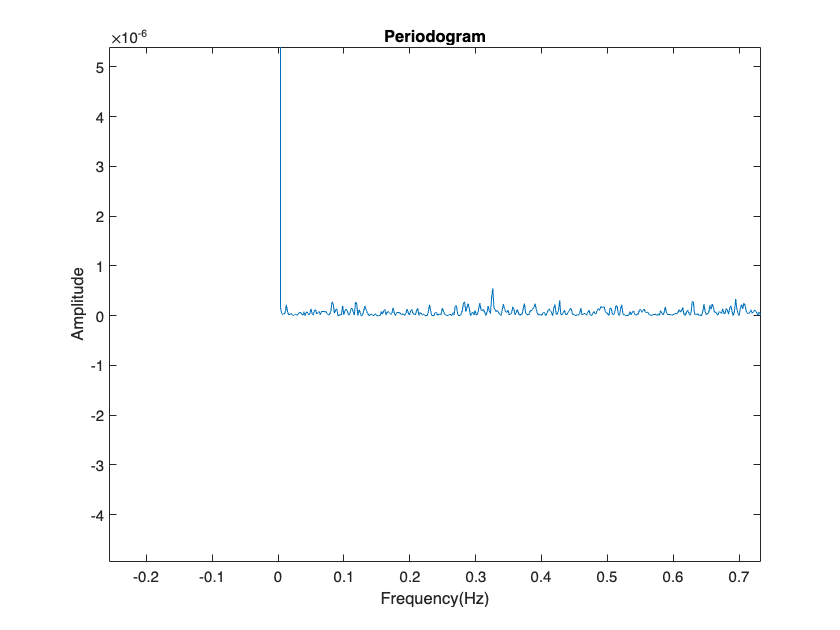

w2 = hanning(N, "periodic");

[pxx, wxx] = pwelch(x_env, w2, 500,N, Fs, "power");
figure
plot(wxx, pxx)
title('Periodogram');  
xlabel('Frequency(Hz)')
ylabel('Amplitude')

STFT

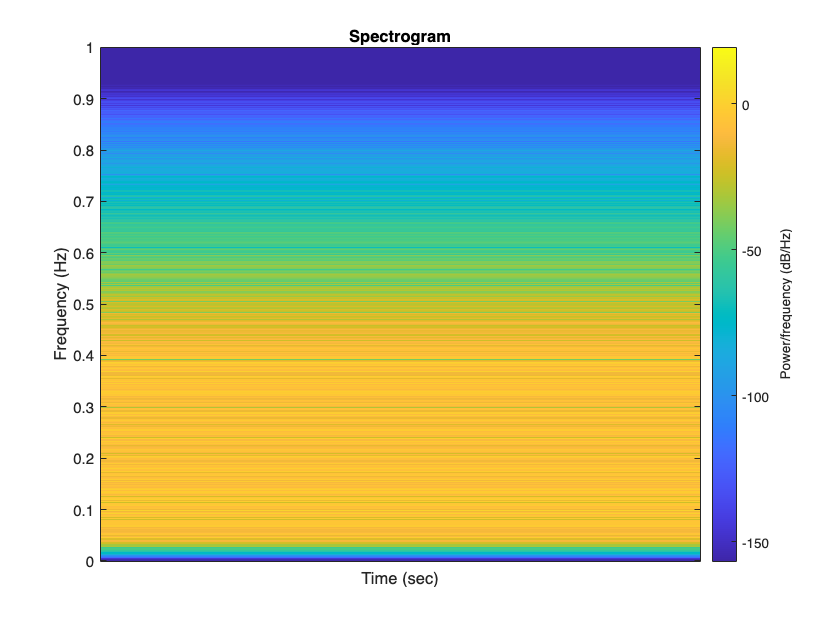

%can get spectrograms from STFT, allows us to visualise sound
% stft(xout, Fs, Window=w2);
% Ax = gca;
% Ax.XLabel.String = 'Time (sec)';

%N length of signal
nsc = floor(N/4.5);
nff = max(256,2^nextpow2(nsc));
ns = 5;
ov = 0.5;
lsc = floor(N/(ns-(ns-1)*ov));

spectrogram(xout,w2,floor(ov*lsc),nff,"yaxis", 2); %increase with freq range with faster breath and further distance

Ax = gca;
title("Spectrogram")
set(gca,'XTick',[0 10 50])
xt = Ax.XTick;
Ax.XTickLabel = xt;
Ax.XLabel.String = 'Time (sec)';


%[s1,f1,t1]=spectrogram(xout,w2,500,NFFT,"yaxis");


STFT 

% M = floor(length(xout)/4.5);
% g = hanning(M, "periodic"); %window
% L = floor(M/2); 
% NDFT = max(256, 2^nextpow2(M));
% lk =0.5; %overlapping
%  
% [sx, fx, tx] = spectrogram(xout);
% [st,ft,tt] = stft(xout,Window=g,OverlapLength=L,FFTLength=NDFT,FrequencyRange="onesided");
%  
% [S,F,T] = pspectrum(xout,Fs,"spectrogram", ...
%      TimeResolution=M/Fs,OverlapPercent=L/M*100, ...
%      Leakage=lk);
%  
% k = (length(xout)-L)/(M-L);
% 
% if k~=floor(k)
%      S = S(:,1:floor(k));
%      T = T(1:floor(k));
% end
% 
% [s,f,t] = spectrogram(xout/sum(g)*sqrt(2),g,L,F,Fs);
%  
% subplot(2,1,1)
% waterplot(sqrt(S),F,T)
% title("pspectrum")
% % 
% subplot(2,1,2)
% waterplot(s,f,t)
% title("spectrogram")

%dff = max(max(sx-st));

% figure;
% subplot(2,1,1)
% waterplot(sx,fx/pi,tx)
% title("Spectrogram")
% subplot(2,1,2)§§§
% waterplot(st,ft/pi,tt/(2*pi))
% title("STFT")


%  function waterplot(s,f,t)
% %  % Waterfall plot of spectrogram
%       waterfall(f,t,abs(s)'.^2)
%       set(gca,XDir="reverse",View=[30 50])
%       xlabel("Frequency Hz")
%       ylabel("Samples")
%       set(gca,'XTick')
%       Ax = gca;
%       xt = Ax.XTick;
%       Ax.XTickLabel = xt;
%       axis([0 3000 0 50 -inf inf])
%  end
